**Lab3_Part2**

**Experiment 3-2**

**1- **Done

**2- **

**a) **Done

**b) **Done

**3-**

%% Parameters
fs = 10e6; % Baseband Sampling Rate (65105 to 61.44e6 Hz)
frame_size = 4096; % Samples per Each Frame (< 2^20)
% Transmitter Parameters
tx_fc = 325e6; % Set Transmitter Center Frequency
% (AD9363: 325-3800MHz) (AD9364: 70-6000MHz)
tx_gain = -30; % Set Transmitter Attenuation as a Negative Gain
% (-89.75 to 0 dB)
tx_address = 'usb:0'; % Set Transmitter Identification Number
% Receiver Parameters
rx_fc = 325e6; % Set Receiver Center Frequency
% (AD9363: 325-3800MHz) (AD9364: 70-6000MHz)
rx_gain = 20; % Set Receiver Gain (-4dB to 71dB)
rx_address = 'usb:0'; % Set Receiver Identification Number
% Initialize ADALM-PLUTO
dev = sdrdev('Pluto'); % Create Radio Object for ADALM-PLUTO
setupSession(dev)

configurePlutoRadio('AD9363'); % Configure ADALM-PLUTO Radio Firmware

## Establishing connection to hardware. This process can take several seconds.


% Define Transmitter Object
tx = sdrtx('Pluto','RadioID',tx_address); % CreateTransmitterSystem Object
tx.CenterFrequency = tx_fc; % Set Transmitter Center Frequency
tx.Gain = tx_gain; % Set Transmitter Gain
tx.BasebandSampleRate = fs; % Set Baseband Sampling Rate
% Define Receiver Object
rx = sdrrx('Pluto','RadioID',rx_address); % Create Receiver System Object
rx.CenterFrequency = rx_fc; % Set Receiver Center Frequency
rx.BasebandSampleRate = fs; % Set Baseband Sampling Rate
rx.SamplesPerFrame = frame_size; % Samples per Each Frame (< 2^20)
rx.GainSource = 'Manual'; % AGC Settings
rx.Gain = rx_gain; % Receiver Gain
rx.OutputDataType = 'double'; % Output Data Type
stop_time = 60;

**4-**

% Transmit Repeat
f_offset = 1e6;
t = (0:2^14-1)'/fs;
sine_wave = exp(1j*2*pi*f_offset*t);
tx.transmitRepeat(sine_wave);

## Establishing connection to hardware. This process can take several seconds.
## Waveform transmission has started successfully and will repeat indefinitely. 
## Call the release method to stop the transmission.


**5-**

**Step 1)**

Done

**Step 2 & 3 & 4 & 5)**

Has been completed in the plotter .m file

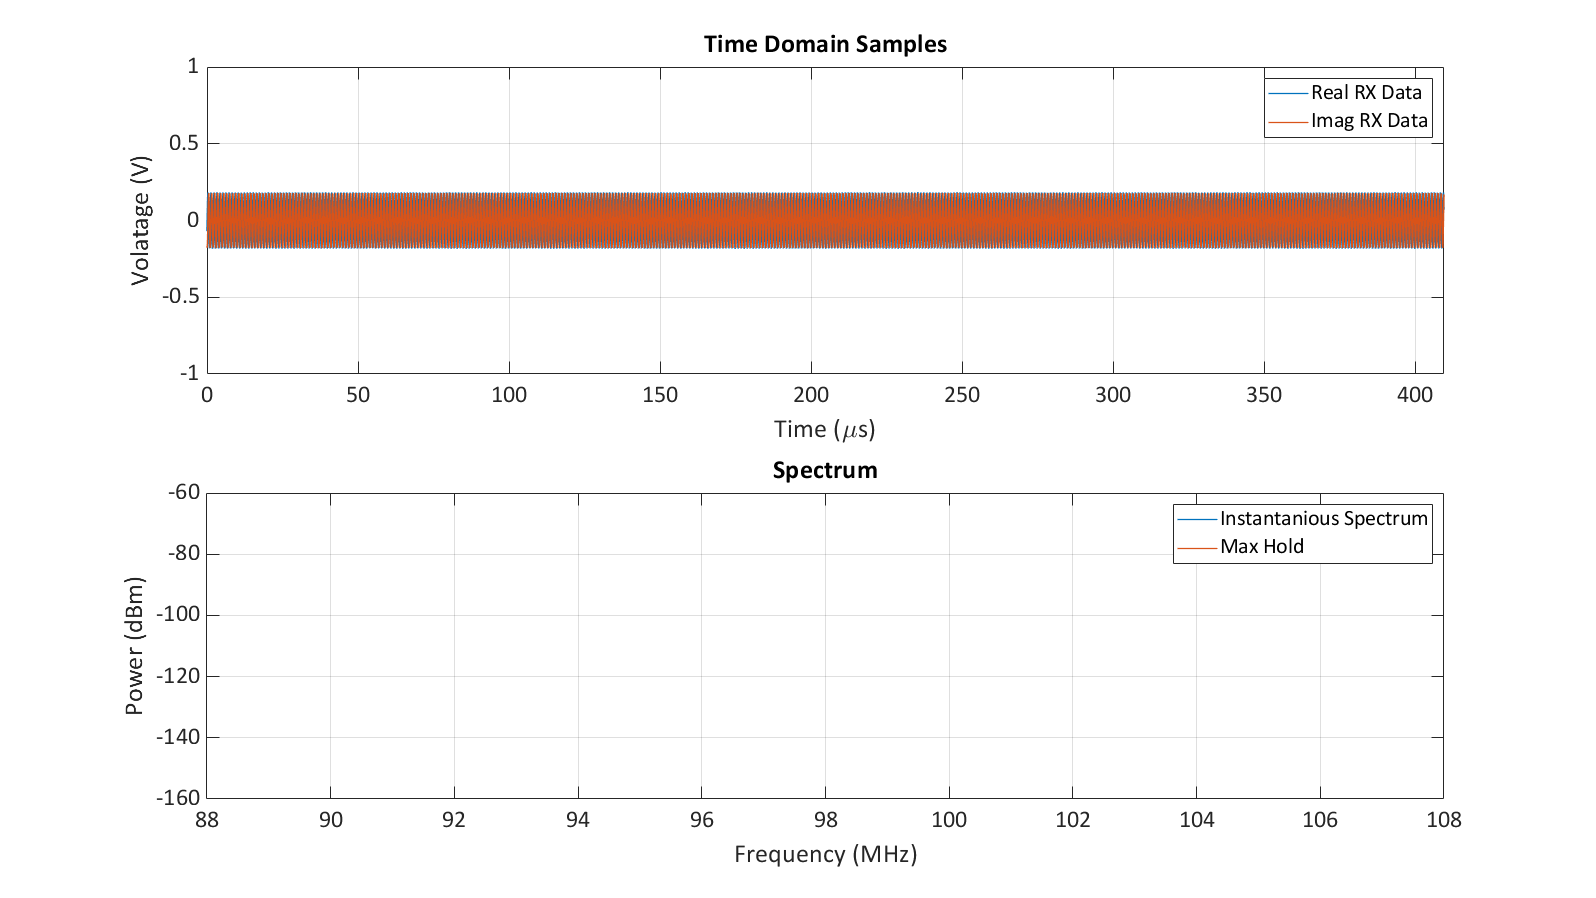

Plotter


%pluto_data = zeros(stop_time,frame_size);
%i=1;

% tic
% while toc<=stop_time
%    pluto_data = rx();
%    pluto_data_fft0 = fftshift(fft(pluto_data,frame_size));
%    pluto_data_fft = db(abs(pluto_data_fft0).^2);
%    f = -fs/2 : fs/frame_size : fs/2 - fs/frame_size ;
%    h = animatedline;
%    addpoints(h,f,pluto_data_fft);
%    drawnow
%    refreshdata
% end

**Step 4)**

%pluto_data_fft0 = fftshift(fft(pluto_data,frame_size));
%pluto_data_fft = db(abs(pluto_data_fft0).^2);

**Step 5)**

%f = -fs/2 : fs/frame_size : fs/2 - fs/frame_size ;


**Experiment 3-3)**

**Part 2)**

**Step 1)**

NO_FM_Stations = 22 (couting the bigger peeks)